%%
clear;clc;clf;
% rng('default');
rng(5);
rng

ans = 包含以下字段的 struct :
     Type: 'twister'
     Seed: 5
    State: [625×1 uint32]


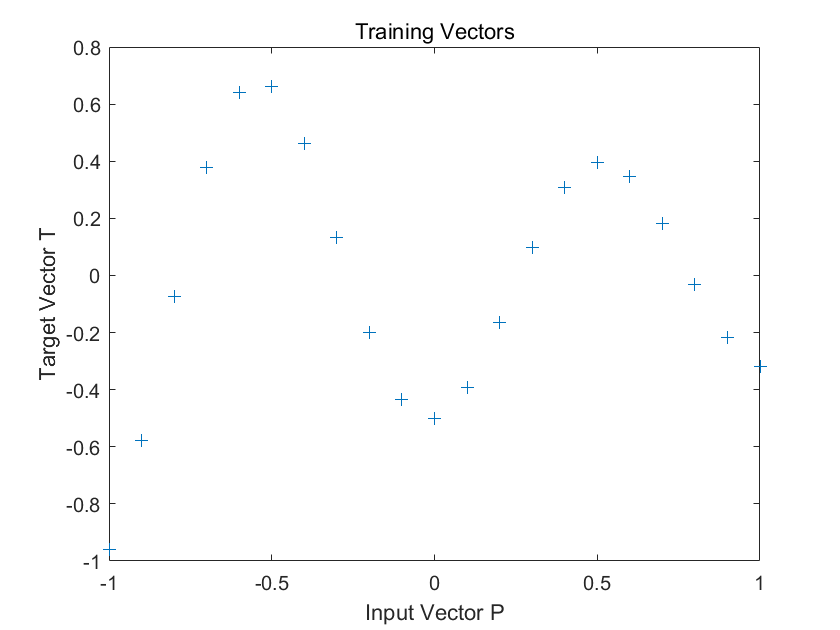

flag=0;   % 1=单步执行；0=连续执行
%设定目标函数值
P = -1:.1:1;
T = [-.9602 -.5770 -.0729  .3771  .6405  .6600  .4609 ...
      .1336 -.2013 -.4344 -.5000 -.3930 -.1647  .0988 ...
      .3072  .3960  .3449  .1816 -.0312 -.2189 -.3201];
plot(P,T,'+');
title('Training Vectors');
xlabel('Input Vector P');
ylabel('Target Vector T');

% set(gcf,'PaperPositionMode','auto');  % 按当前窗口大小复制图片
% print(gcf,'-dpng','1.png')

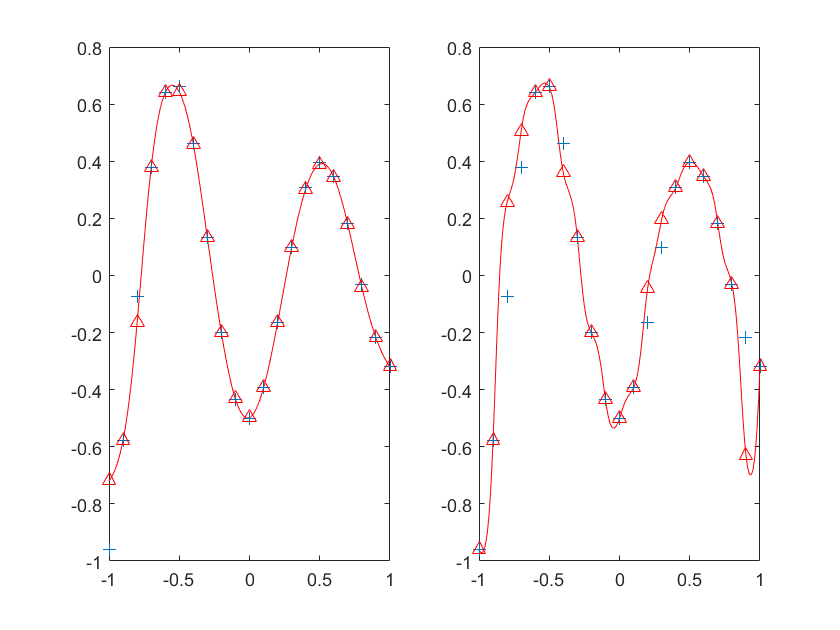

test_p=-1:0.01:1;
net_5=feedforwardnet(5);
net_5=train(net_5,P,T);
view(net_5)
train_y_5=net_5(P);
test_y_5=net_5(test_p);
figure
subplot(1,2,1)
plot(test_p,test_y_5,'r');
hold on
plot(P,T,'+');
plot(P,train_y_5,'r^')

net_15=feedforwardnet(15);
net_15=train(net_15,P,T);
view(net_15)
train_y_15=net_15(P);
test_y_15=net_15(test_p);
subplot(1,2,2)
plot(test_p,test_y_15,'r');
hold on
plot(P,T,'+');
plot(P,train_y_15,'r^')

train_set=1:0.1:5;
test_setin=1:0.05:5;
test_setout=5:0.05:10;
total_set=[test_setin,test_setout];

real_val=exp(-1*total_set)+total_set.^0.5.*sin(pi*total_set);
train_real=exp(-1*train_set)+train_set.^0.5.*sin(pi*train_set);

net_5=feedforwardnet(5);
net_5=train(net_5,train_set,train_real);
view(net_5)
train_set_bytrain=net_5(train_set)

train_set_bytrain =     0.3679    0.0085   -0.3423   -0.6497   -0.8790   -1.0020   -1.0011   -0.8719   -0.6234   -0.2770    0.1345    0.5698    0.9828    1.3277    1.5644    1.6630    1.6073    1.3963    1.0447    0.5819    0.0502   -0.4991   -1.0111   -1.4331   -1.7201   -1.8402   -1.7769   -1.5316   -1.1240   -0.5904    0.0184    0.6426    1.2197    1.6908    2.0067    2.1323    2.0502    1.7632    1.2957    0.6913    0.0068


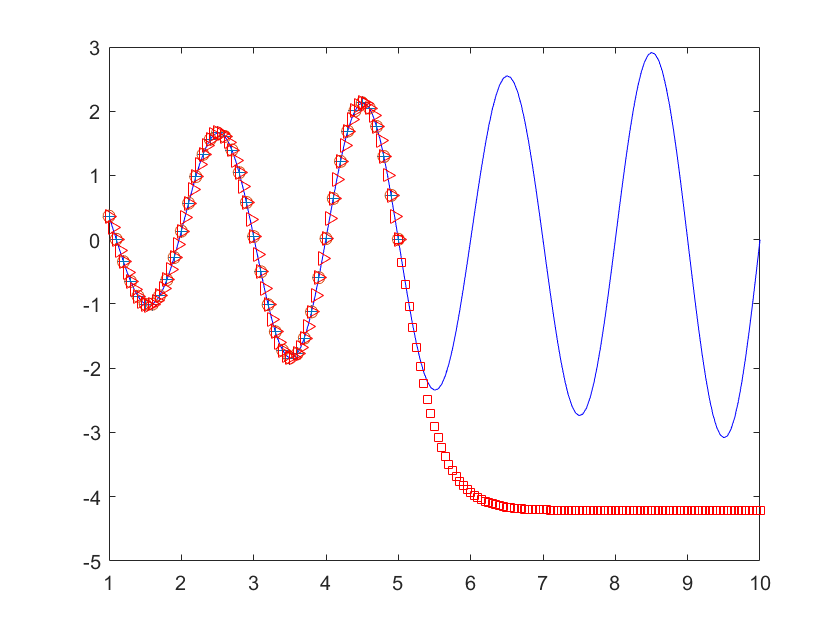

test_setin_bytrain=net_5(test_setin);
test_setout_bytrain=net_5(test_setout);

figure
plot(total_set,real_val,'b');
hold on
plot(train_set,train_real,'+');
plot(train_set,train_set_bytrain,'o');
plot(test_setin,test_setin_bytrain,'r>');
plot(test_setout,test_setout_bytrain,'rs');